%% 3번 문제
clear; clc;

rng('default');

% (a)
N = randn(100000, 1);

% (b) 
A = 1.8;
S = A + N;

% (c)
detection_event = S >= 1.2;

% (d) 
success_rate = mean(detection_event);
fprintf('=== 3번 결과 ===\n');

=== 3번 결과 ===


fprintf('감지 성공률: %.2f%%\n', success_rate * 100);

감지 성공률: 72.72%


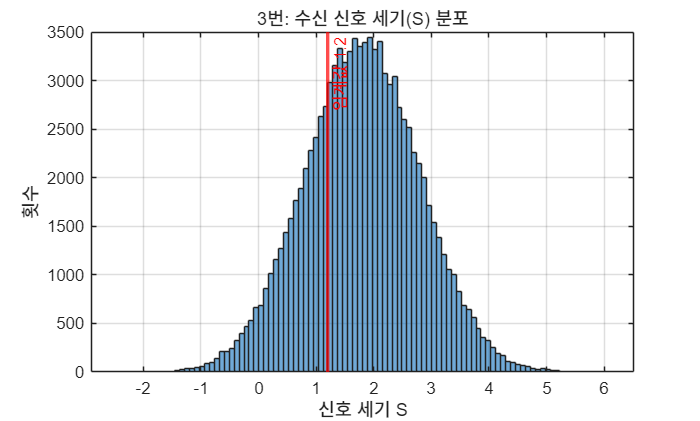


% (e) 
figure(3);
histogram(S, 100);
hold on;
xline(1.2, 'r-', '임계값 1.2', 'LineWidth', 2);
hold off;
title('3번: 수신 신호 세기(S) 분포');
xlabel('신호 세기 S');
ylabel('횟수');
grid on;